# Week 5 Exercise 4

clear;
close all;

Part (a)

syms y(t)
w = 1;
l = 0.5;

myode = diff(y,2) + 2*l*w*diff(y) + w^2*y == 0 

$$myode(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+\frac{\partial }{\partial t}y\left(t\right)+y\left(t\right)=0$$

d = diff(y) % First Derivative

$$d(t) = \frac{\partial }{\partial t}y\left(t\right)$$

mycond = [y(0)==10 d(0)==0] % Initial Conditions

$$mycond = \left(\begin{array}{cc} y\left(0\right)=10 & \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

g = dsolve(myode, mycond) % Solving Eq. 6 with Initial Conditions

$$g = \frac{10\,{\mathrm{e}}^{-\frac{t}{2}}\,\left(3\,\cos\left(\frac{\sqrt{3}\,t}{2}\right)+\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)\right)}{3}$$

fplot(g, [0 20], 'LineWidth', 2)

Part (b)

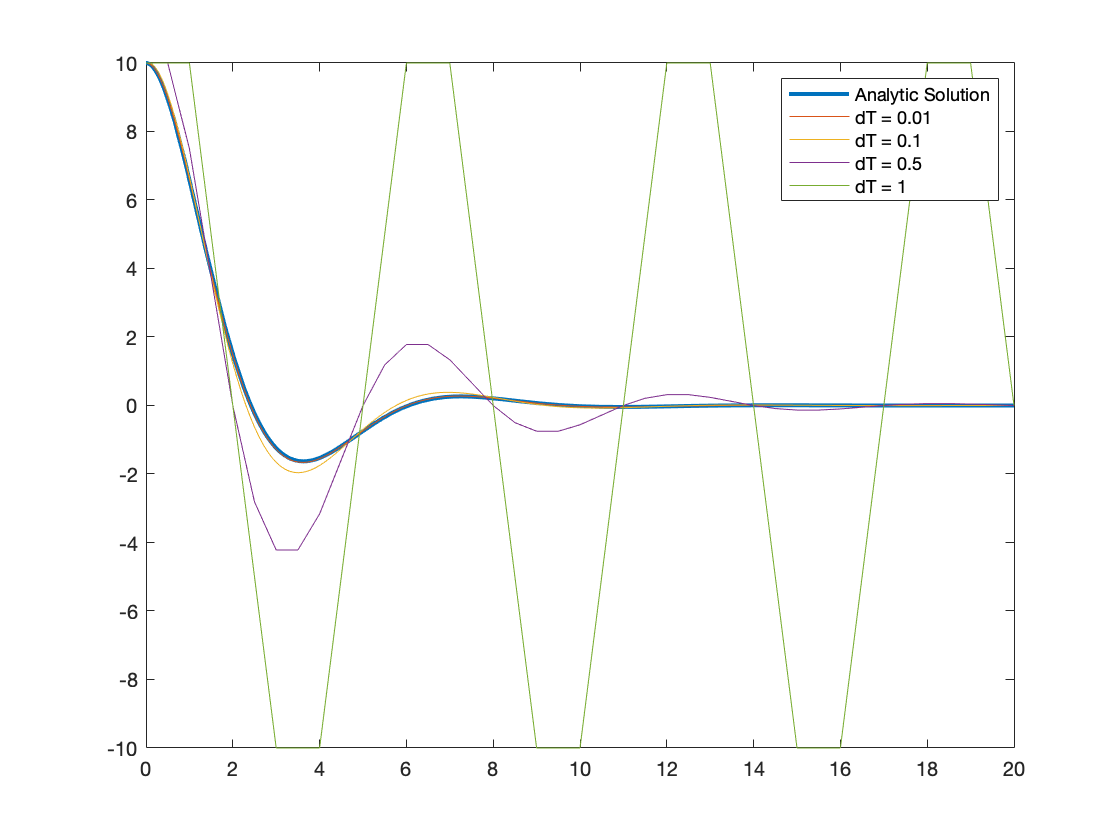

A = [  0     1
     -w^2   -2*l*w];
x0 = [10; 0];
T = 20;

hold on
for dT = [0.01 0.1 0.5 1]
    [t,x] = f_Euler(A, x0, dT, T);
    plot(t,x(1,:))
end
legend("Analytic Solution", "dT = 0.01", "dT = 0.1", "dT = 0.5", "dT = 1")

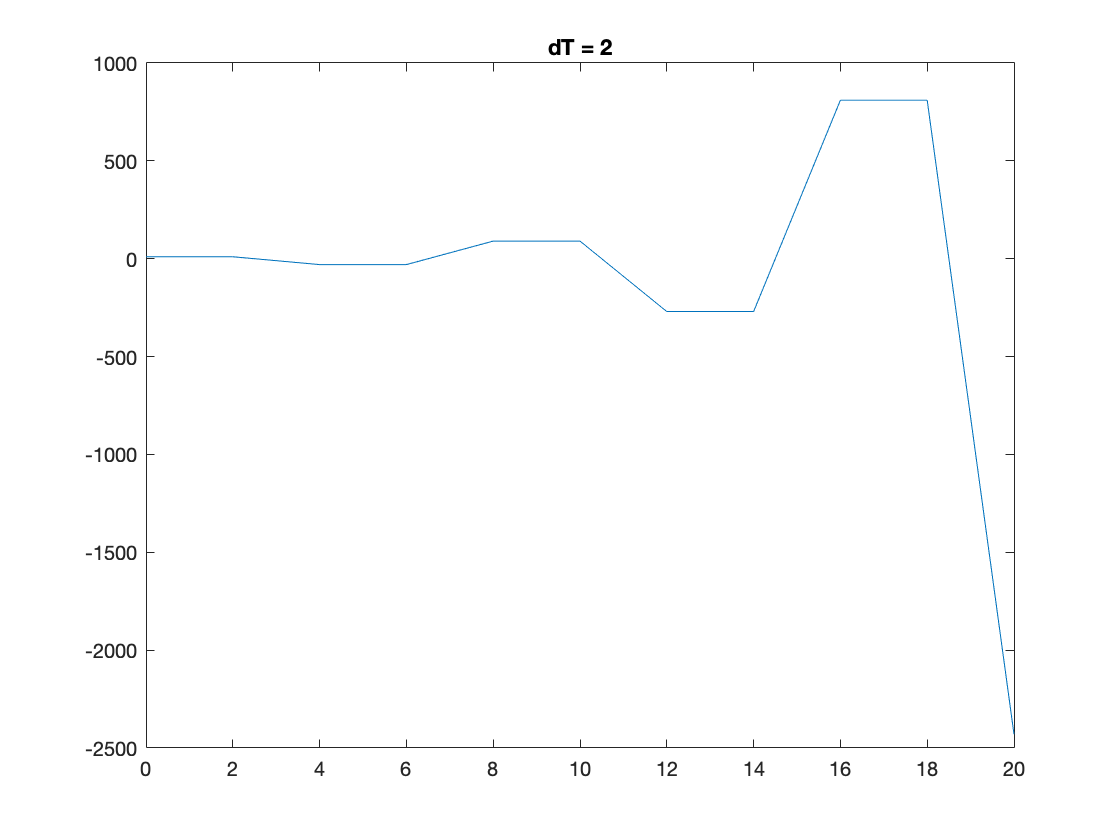


dT = 2;
[t,x] = f_Euler(A, x0, dT, T);
figure(2)
plot(t,x(1,:))
title("dT = 2")

% Step size is inversely related to accuracy: the larger the
% step size, the worse the approximation. This is especially
% true for dT = 2, shown on its own graph due to it massive 
% errors.


Part (c)

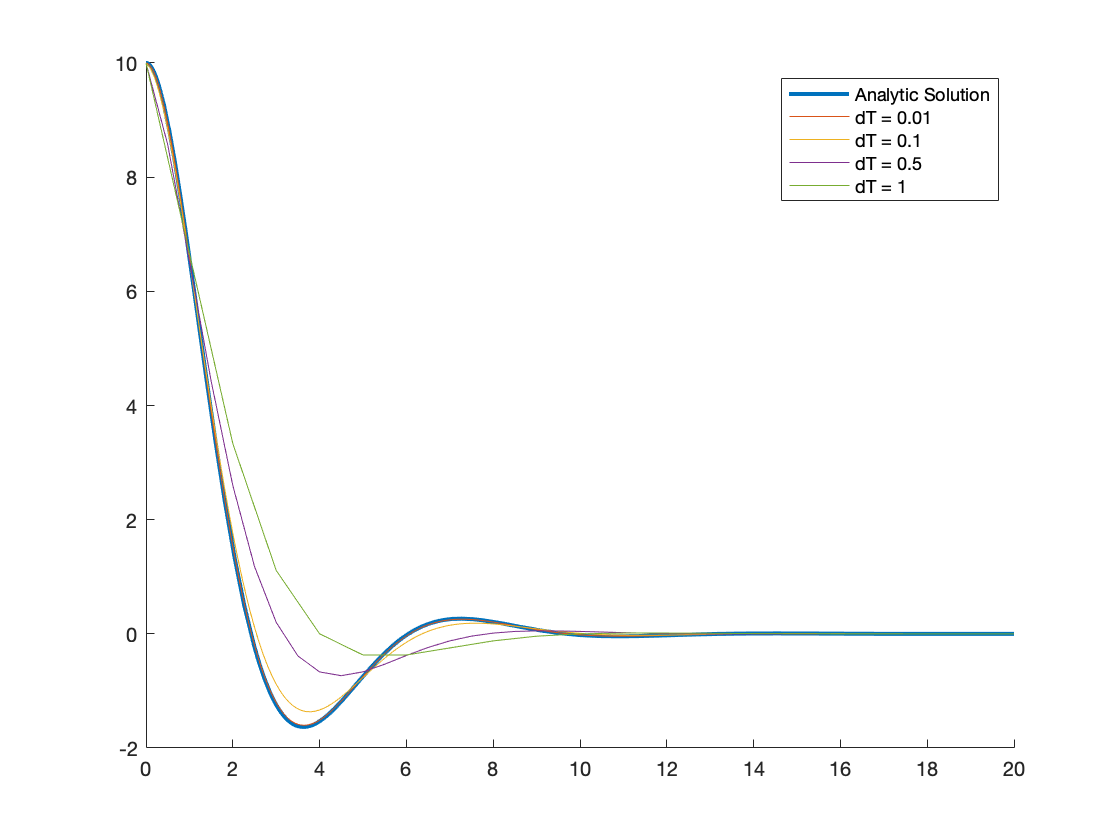

figure(3)
hold on
fplot(g, [0 20], 'LineWidth', 2)
for dT = [0.01 0.1 0.5 1]
    [t,x] = b_Euler(A, x0, dT, T);
    plot(t,x(1,:))
end
legend("Analytic Solution", "dT = 0.01", "dT = 0.1", "dT = 0.5", "dT = 1")

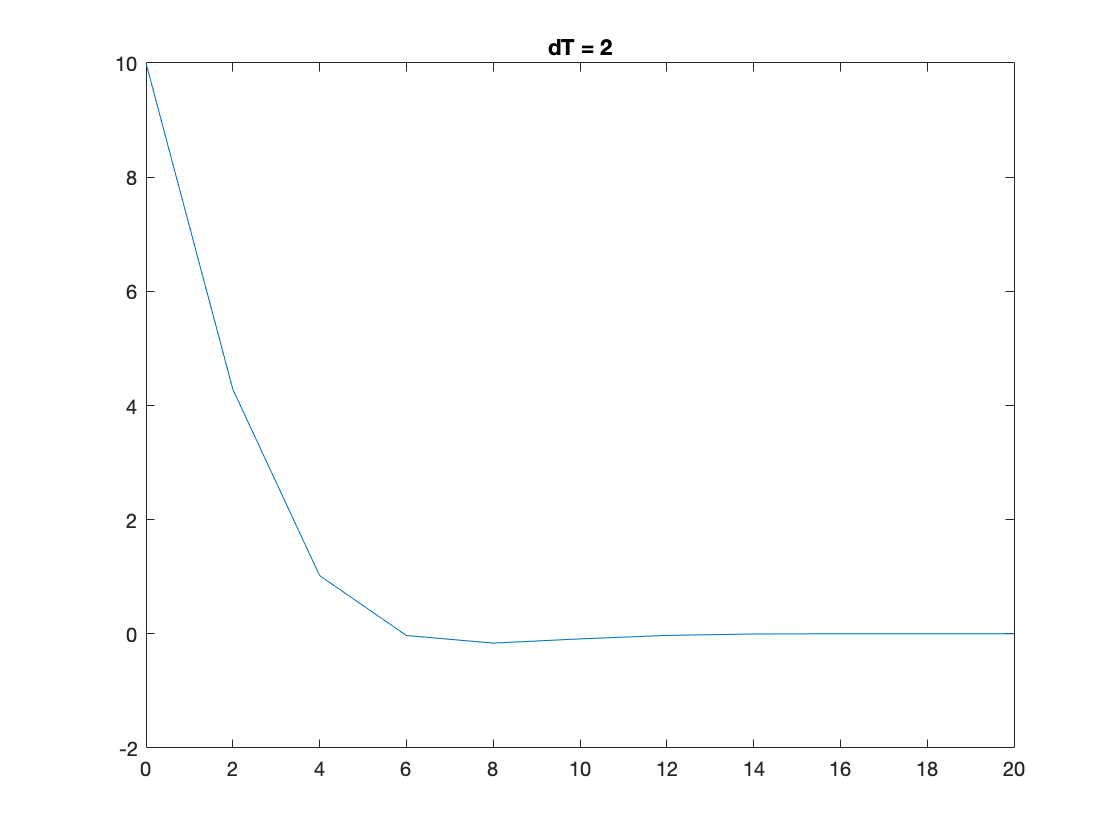


dT = 2;
[t,x] = b_Euler(A, x0, dT, T);
figure(4)
plot(t,x(1,:))
title("dT = 2")

% Step size is still inversely related to accuracy, but not
% as exponentially as before. This is the same for dT = 2 which
% more closely resembles the graphs above. 


Part (d)

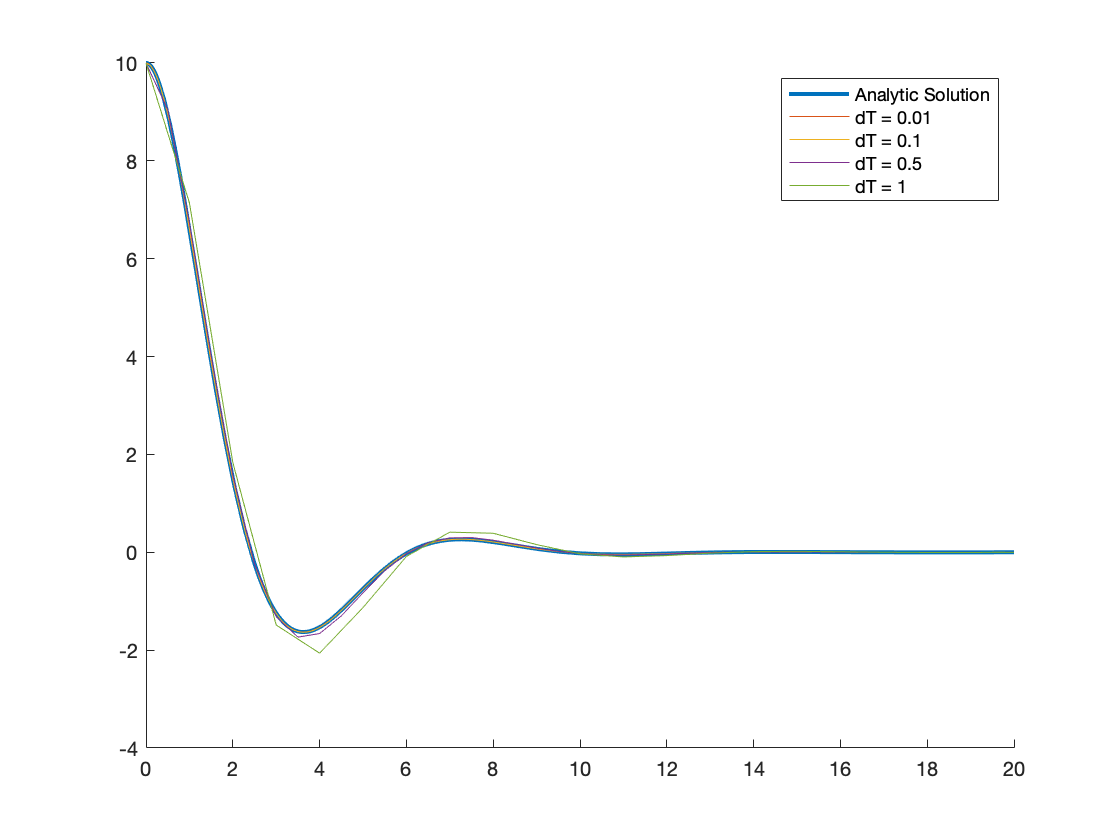

figure(5)
hold on
fplot(g, [0 20], 'LineWidth', 2)
for dT = [0.01 0.1 0.5 1]
    [t,x] = trapz_rule(A, x0, dT, T);
    plot(t,x(1,:))
end
legend("Analytic Solution", "dT = 0.01", "dT = 0.1", "dT = 0.5", "dT = 1")
hold off

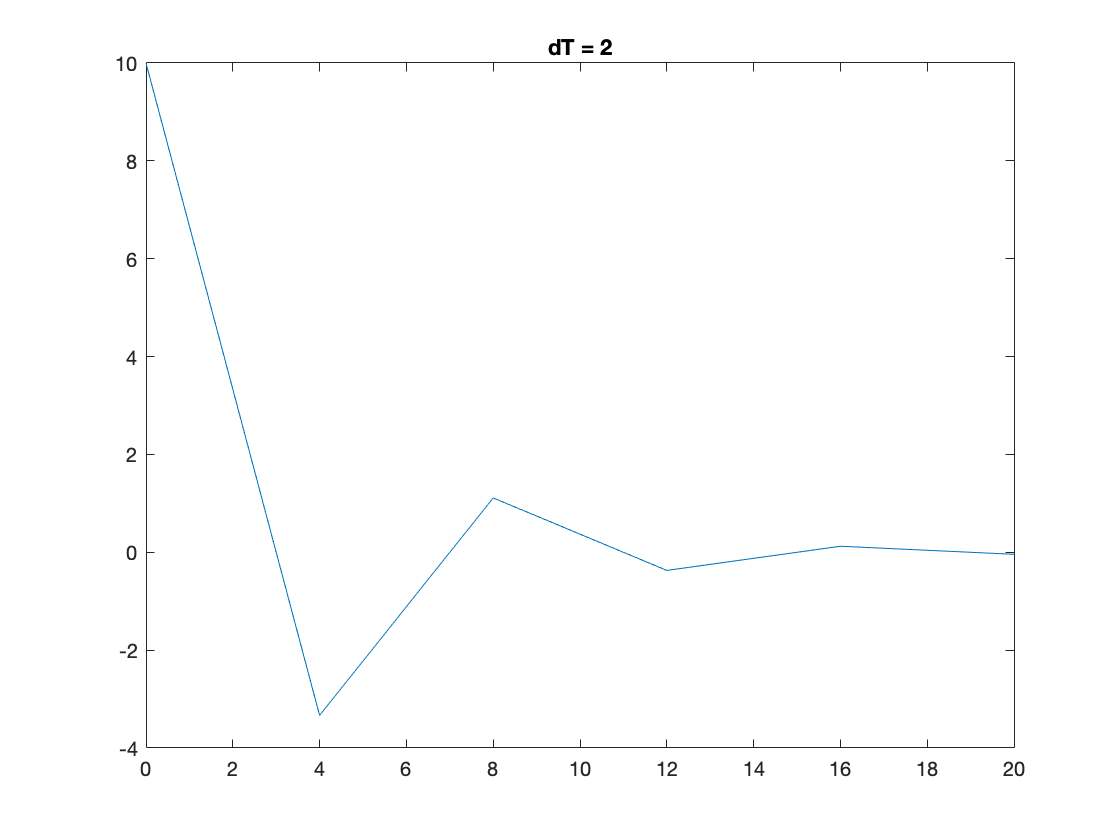


dT = 2;
[t,x] = trapz_rule(A, x0, dT, T);
figure(6)
plot(t,x(1,:))
title("dT = 2")

% Step size is still inversely related to accuracy, but not
% as exponentially as before. This is the same for dT = 2 which
% more closely resembles the graphs above. 


Part (e)

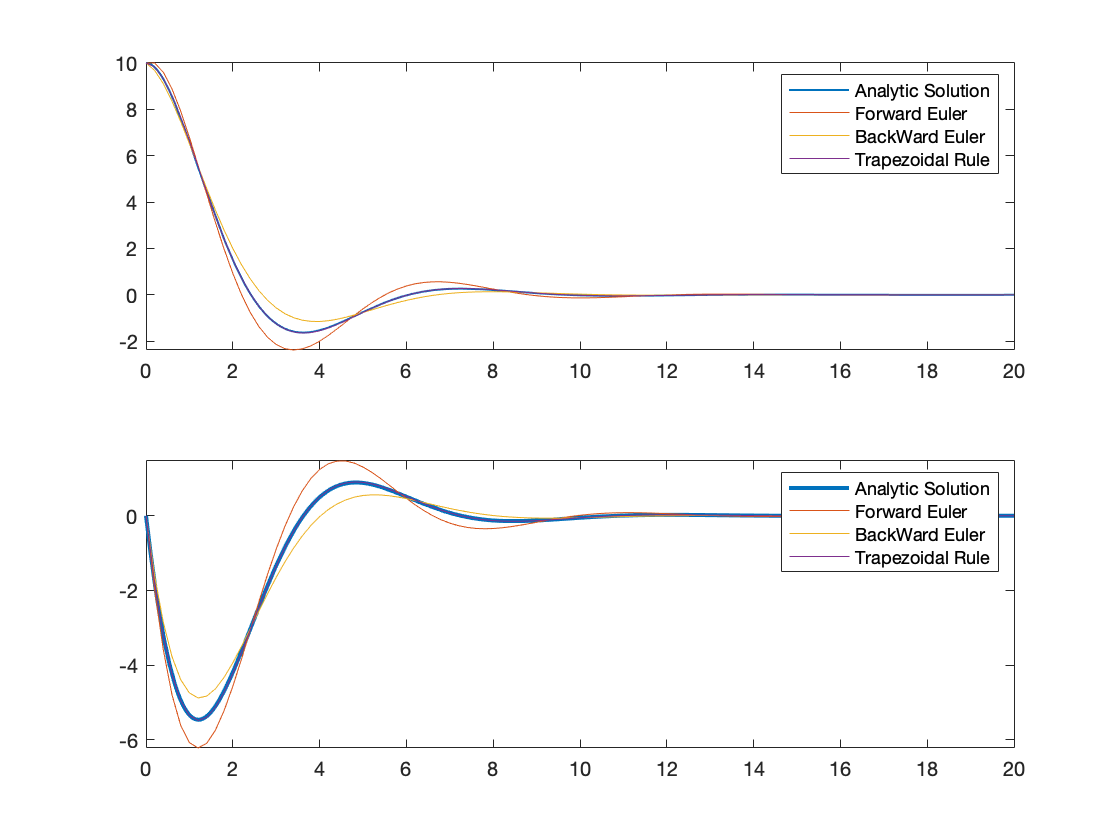

%figure(7)
subplot(2,1,1)
fplot(g, [0 20], 'LineWidth', 1)
dT = 0.2;
hold on
[t,x] = f_Euler(A, x0, dT, T);
plot(t,x(1,:))
[t,x] = b_Euler(A, x0, dT, T);
plot(t,x(1,:))
[t,x] = trapz_rule(A, x0, dT, T);
plot(t,x(1,:))
legend("Analytic Solution", "Forward Euler", "BackWard Euler", "Trapezoidal Rule")
hold off
subplot(2,1,2)

fplot(diff(g), [0 20], 'LineWidth', 2)
hold on
[t,x] = f_Euler(A, x0, dT, T);
plot(t,x(2,:))
[t,x] = b_Euler(A, x0, dT, T);
plot(t,x(2,:))
[t,x] = trapz_rule(A, x0, dT, T);
plot(t,x(2,:))
legend("Analytic Solution", "Forward Euler", "BackWard Euler", "Trapezoidal Rule")